# Radio FM – dekodowanie

load Data

fs = 3.2e6;         % sampling frequency
N  = 32e6;         % number of samples (IQ)
fc = 0.40e6;        % central frequency of MF station

bwSERV = 80e3;     % bandwidth of an FM service (bandwidth ~= sampling frequency!)
bwAUDIO = 16e3;     % bandwidth of an FM audio (bandwidth == 1/2 * sampling frequency!)

f = fopen('samples_100MHz_fs3200kHz.raw');
s = fread(f, 2*N, 'uint8');
fclose(f);

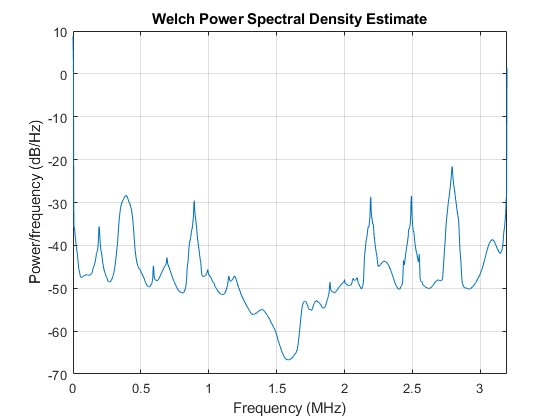



% IQ --> complex
wideband_signal = s(1:2:end) + sqrt(-1)*s(2:2:end);
  
figure
psd(spectrum.welch('Hamming',1024), wideband_signal(1:10e6),'Fs',fs);

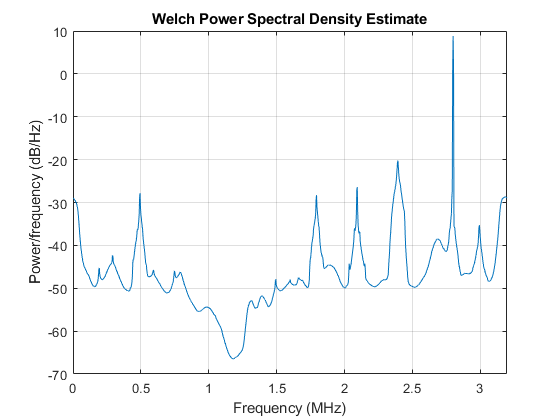


% Extract carrier of selected service, then shift in frequency the selected service to the baseband
wideband_signal_shifted = wideband_signal .* exp(-sqrt(-1)*2*pi*fc/fs*[0:N-1]');

figure
psd(spectrum.welch('Hamming',1024), wideband_signal_shifted(1:10e6),'Fs',fs);


%spectrogram(wideband_signal_shifted)

Zmieniony filtr

% Filter out the service from the wide-band signal (1)
n = 4; Wn = 80e3/(fs/2);
[b,a] = butter(n,Wn)

b = 	1.0e+-3 *

    0.0312    0.1250    0.1874    0.1250    0.0312


a =     1.0000   -3.5897    4.8513   -2.9241    0.6630


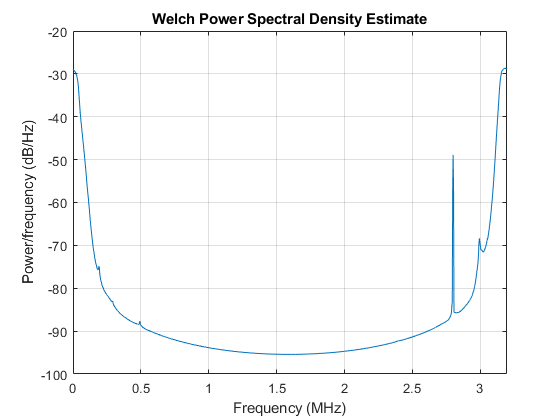

wideband_signal_filtered = filter( b, a, wideband_signal_shifted );

% Down-sample to service bandwidth - bwSERV = new sampling rate
x = wideband_signal_filtered( 1 : fs/bwSERV : end );

figure
psd(spectrum.welch('Hamming',1024), wideband_signal_filtered(1:10e6),'Fs',fs);


% FM demodulation
dx = x(2:end).*conj(x(1:end-1));
y = atan2( imag(dx), real(dx) );

% Decimate to audio signal bandwidth bwAUDIO (2)


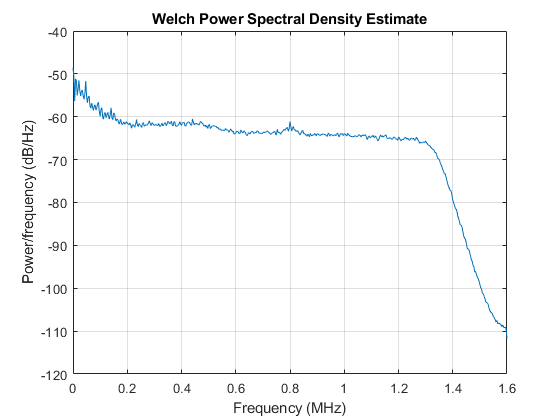

f_norm=bwAUDIO/bwSERV; % decimate (1/5) % normalized cut off frequency
[ba,aa]=butter(4,f_norm); % nth-order lowpass digital Butterworth filter 
y = filter( ba, aa, y ); % antyaliasing filter
ym = decimate(y,5);

figure
psd(spectrum.welch('Hamming',1024), ym,'Fs',fs);


%y = …. % antyaliasing filter
%ym = y(bwSERV/bwAUDIO ); % decimate (1/5)

% De-emfaza, flat characteristics to 2.1 kHz, then falling 20 dB/decade
% (…)
% Listen to the final result

ym = ym-mean(ym); ym = ym/(1.001*max(abs(ym)));
%soundsc( ym, bwAUDIO);